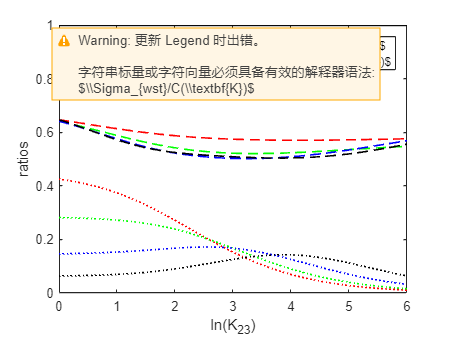

clear all;
close all;
load('Phasedata.mat');
load('K13s.mat');
load('K23s.mat');
linew = 1.2;
color = ['r','g','b','k'];
K13 = [21 41 61 81];
plt=zeros(1,3);
for m = 1:1:4
    i = K13(m);
    T =30;
    Cost_exact = zeros(1,length(K13s));
    Cost_GraphW = zeros(1,length(K13s));
    Cost_linearW = zeros(1,length(K13s));
    Cost_linearC = zeros(1,length(K13s));
    Cost_bareC = zeros(1,length(K13s));
    for j=1:1:121
        p1 = Phasedata.P1Dat{i,j};
        p2 = Phasedata.P2Dat{i,j};
        k12 = Phasedata.K12Dat{i,j};
        k21 = Phasedata.K21Dat{i,j};
        k13 = Phasedata.K13Dat{i,j};
        k31 = Phasedata.K31Dat{i,j};
        k23 = Phasedata.K23Dat{i,j};
        k32 = Phasedata.K32Dat{i,j};
        Cost_exact(j) = entropy_cal(p1,p2,k12,k21,k13,k31,k23,k32,T)*6;   %T=30, tau=5, scale = T/tau
        Cost_GraphW(j) = GraphW_cal(p1,p2,k12,k21,k13,k31,k23,k32,T)*6;
        Cost_linearW(j) = linearW(5,K13s(i),K13s(j))*6;
        Cost_bareC(j) = bareC(5,K13s(i),K13s(j))*6;

    end
    
    plt(1) = plot(log(K13s),Cost_exact./Cost_exact,color(m),LineWidth=linew);
    hold on     
    plt(2) = plot(log(K13s),Cost_bareC./Cost_exact,color(m),LineWidth=linew,LineStyle='--');
    hold on 
    plt(3) = plot(log(K13s),Cost_linearW./Cost_exact,color(m),LineWidth=linew,LineStyle=":");
    hold on
%     plt(4) = plot(log(K13s),Cost_GraphW./Cost_exact,color(m),LineWidth=linew,LineStyle="-.");
%     hold on
%     plt(1) = plot(log(K13s),Cost_linearC,color(m),LineWidth=linew,Marker='o');
%     hold on
%     plt(2) = plot(log(K13s),Cost_linearW,color(m),LineWidth=linew,LineStyle='-.');
end
    xlabel('ln(K_{23})')
    ylabel('ratios')
%     legend(plt,'ln(K_{13}) = 1','ln(K_{13}) = 2','ln(K_{13}) = 3','ln(K_{13}) = 4')
    legend(plt(2:3),'$\Sigma_{kh}/C(\textbf{K})$','$\Sigma_{wst}/C(\textbf{K})$')